# DC-Motor Controll

clear global
close all
clc

load("measurement.mat") % Load Measurements from the Physical System

## Simulation White-Box Model

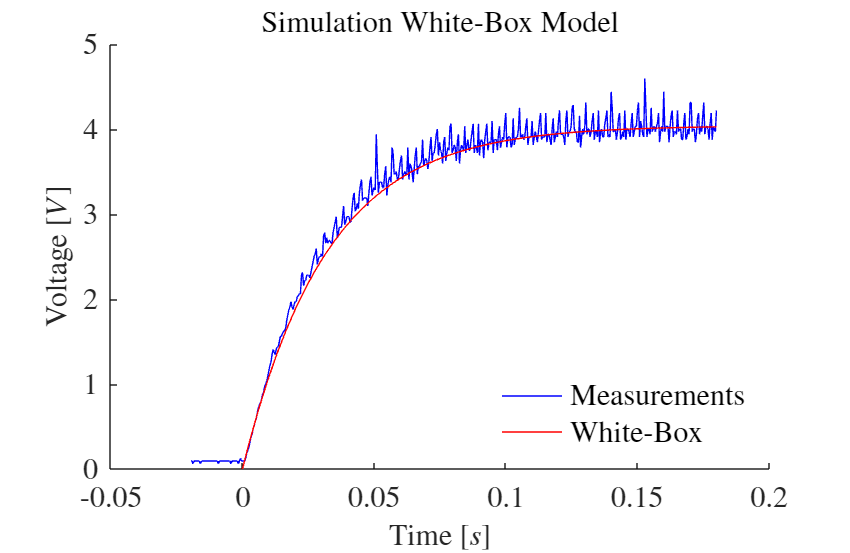

simStepAmp  = 5;    % Amplitude of the Step [V]
simTimeStop = 0.18; % Stop Simulation at Time [s]

Ra  = 8;         % Armature Resistance [Ohm]
Kg  = 0.015;     % Generator constant of the Motor and the Generator[Vs]
J   = 9*10^-7;   % Moment of Inertia [kgm^2]
Mgr = 1.8*10^-3; % Sliding Friction [Nm]   

res = sim('simDc.slx');
wb_time  = res.input.time; % wb -> White-Box Model
wb_input = res.input.data;
wb_u     = res.u.data;
wb_rpm   = res.rpm.data;

hfig = figure;
ax = axes('Parent', hfig, 'NextPlot', 'add');

plot(ax, md_time, md_u, 'blue')
plot(ax, wb_time, wb_u, 'red')

title(ax, 'Simulation White-Box Model')
legend(ax, 'Measurements', 'White-Box', 'Location', 'SouthEast')
xlabel(ax, 'Time [$s$]')
ylabel(ax, 'Voltage [$V$]')
figureCfg(hfig)

## Simulation Black-Box Model

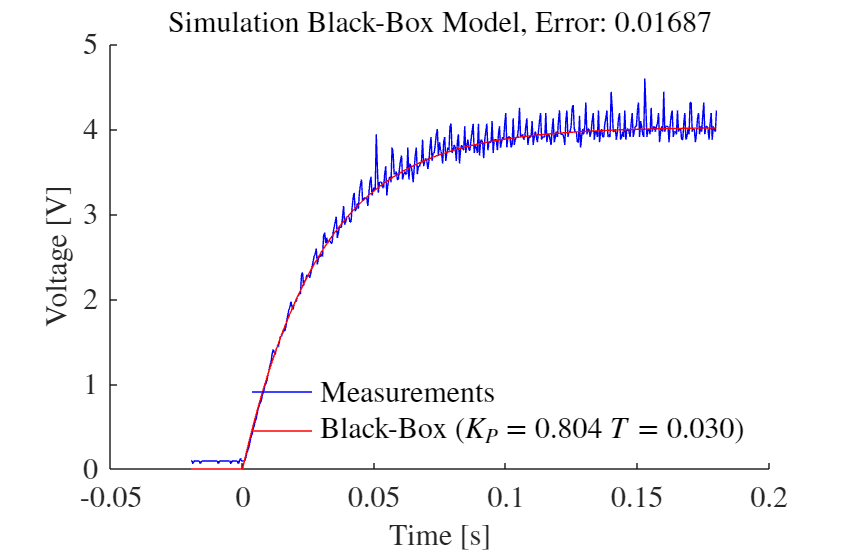

Kp = 4/5; % Initial Values for PT-1
T  = 0.02;
p0 = [Kp; T];

optOptions = optimset('Disp', 'notify', 'MaxIter', 200);
visualisierung = 1;

[pk, ~, ~, ~] = fminsearch(@costFunction, p0, optOptions, md_time, md_u, visualisierung);

bb_time = md_time;
bb_u    = pt1(bb_time, pk(1),pk(2));

## Comparing Both Models

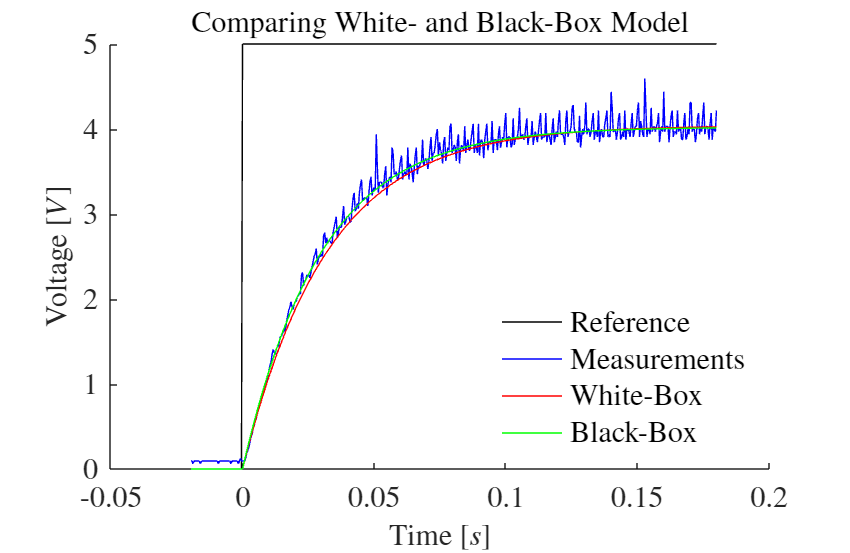

hfig = figure;
ax = axes('Parent', hfig, 'NextPlot', 'add');

plot(ax, md_time, simStepAmp * heaviside(md_time), 'black')
plot(ax, md_time, md_u, 'blue')
plot(ax, wb_time, wb_u, 'red')
plot(ax, bb_time, bb_u, 'green')

title(ax, 'Comparing White- and Black-Box Model');
legend(ax, 'Reference', 'Measurements', 'White-Box', 'Black-Box', 'Location','southeast')
xlabel(ax, 'Time [$s$]')
ylabel(ax, 'Voltage [$V$]')
figureCfg(hfig)

## PI-Controller

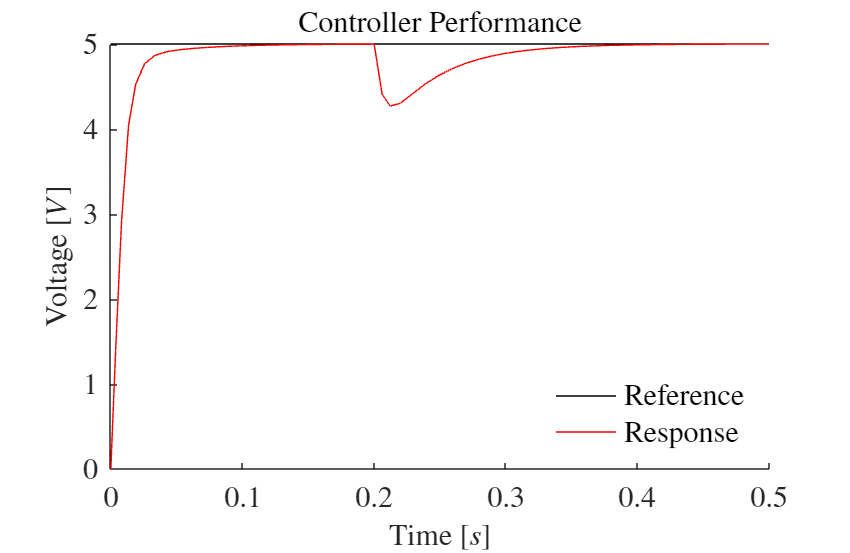

simStepAmp      = 5;    % Amplitude of the Step [V]
simTimeStop     = 0.5;  % Stop Simulation at Time [s]
simTimePayload  = 0.2;  % Start time of the Load [s]
simValuePayload = 0.01; % Magnitude of the Load [Nm]

Tn = 0.04;
Kp = 5;

simSaturationLow = -14; % Upper and Lower Bound for actuator
simSaturationHigh = 14;

res = sim('simDcControlled.slx');
cm_time = res.reference.time;
cm_ref  = res.reference.data;
cm_u    = res.response.data;
cm_akt  = res.actuator.data;

hfig = figure;
ax = axes('Parent', hfig, 'NextPlot', 'add');

plot(ax, cm_time, cm_ref, 'black')
plot(ax, cm_time, cm_u, 'red')

title(ax, 'Controller Performance')
legend(ax, 'Reference', 'Response', 'location', 'SouthEast')
xlabel(ax, 'Time [$s$]')
ylabel(ax, 'Voltage [$V$]')
figureCfg(hfig)

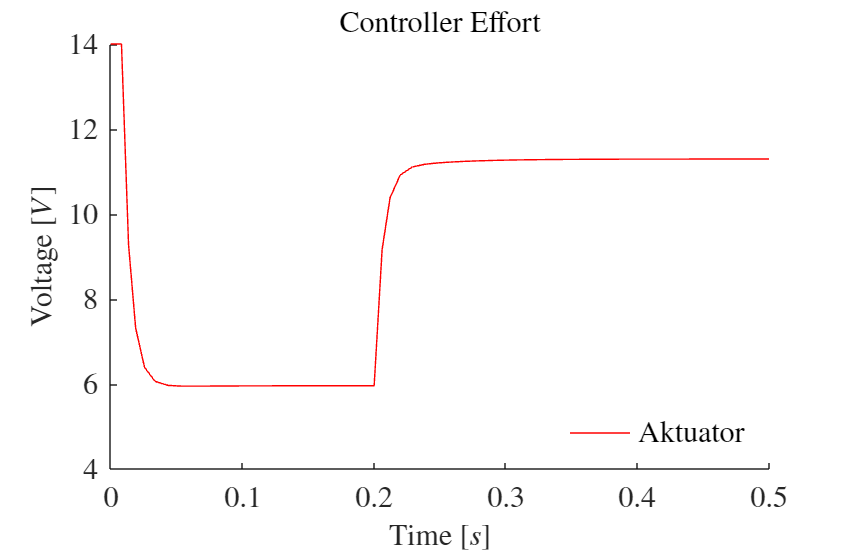

hfig = figure;
ax = axes('Parent', hfig, 'NextPlot', 'add');

plot(ax, cm_time, cm_akt, 'red')

title(ax, 'Controller Effort')
legend(ax, 'Aktuator', 'location', 'SouthEast')
xlabel(ax, 'Time [$s$]')
ylabel(ax, 'Voltage [$V$]')
figureCfg(hfig)